%Class Data

sigma = [1 0 0 ; 0 1 0; 0 0 1]; 
w1 = mvnrnd([4,2,3], sigma, 100);
w2 = mvnrnd([9,4,-5], sigma, 100);
w3 = mvnrnd([-5,-7,8], sigma, 100);


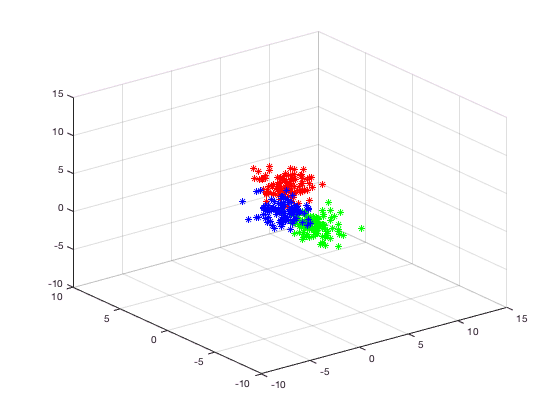

% Plot Class Data
scatter3(w1(:,1), w1(:,2), w1(:,3), '*r')
hold on; 
scatter3(w2(:,1), w2(:,2), w2(:,3), '*g')
scatter3(w3(:,1), w3(:,2), w3(:,3), '*b')
hold off; 

% FLDA 

% Calculating the mean of each class
w1_mean = mean(w1); w2_mean = mean(w2); w3_mean = mean(w3);
% Sutracting the mean of each class from the value 
w1_u = w1-w1_mean; w2_u = w2-w2_mean; w3_u = w3-w3_mean;

% Building the within class scatter 
S1 = (w1_u)'*(w1_u);
S2 = (w2_u)'*(w2_u);
S3 = (w3_u)'*(w3_u);
Sw = S1+S2+S3

Sw =   316.5077   11.5257  -30.5652
   11.5257  301.4987  -21.1700
  -30.5652  -21.1700  273.5306



% Building the total class scatter 
wT = [w1; w2 ;w3];
wT_mean = mean(wT);
wT_u = wT-wT_mean;
St = (wT_u)'*(wT_u)

St =    1.0e+04 *

    1.0284    0.8160   -0.8923
    0.8160    0.7202   -0.6840
   -0.8923   -0.6840    0.9059



% Building the between class scatter 
Sb = St-Sw

Sb =    1.0e+03 *

    9.9674    8.1487   -8.8927
    8.1487    6.9009   -6.8190
   -8.8927   -6.8190    8.7850



% Time to find w 
[V,D] = eig(inv(Sw)*Sb);
[d, ind] = sort(diag(D));
D_sorted = D(ind, ind);
V_sorted = V(:, ind);
% DESIRED NUMBER OF NEW DIMENSIONS IS GONNA BE 2 

w = [V_sorted(:,length(V_sorted)), V_sorted(:,length(V_sorted)-1)]

w =    -0.6038    0.2147
   -0.5119    0.6017
    0.6110    0.7694


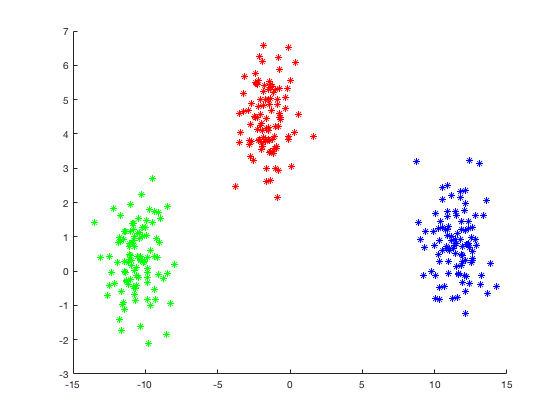


% Transforming original datasets 
w1_transformed = w1*w;
w2_transformed = w2*w;
w3_transformed = w3*w;

% Plotting the reduced Data 
scatter(w1_transformed(:,1), w1_transformed(:,2), '*r')
hold on; 
scatter(w2_transformed(:,1), w2_transformed(:,2), '*g')
scatter(w3_transformed(:,1), w3_transformed(:,2), '*b')